# Chapter 6, Section 5 (Part 1)

The goal of this activity is to introduce what is known as a **least squares** solution of the equation $A\textbf x=\textbf b$. Let's begin with an example.

# Example #1

Consider


$$A=\pmatrix{2 & 1 \cr 1 & 2\cr 0 & 0}\qquad\text{and}\qquad\textbf b=\pmatrix{4\cr 4\cr 2}$$


Does the system $A\textbf x=\textbf b$ have a solution?

**Solution:** Let's try to solve this with Matlab. Our system in matrix form is:


$$\pmatrix{2 & 1\cr 1 & 2\cr 0 & 0}\pmatrix{x_1\cr x_2}=\pmatrix{4\cr 4\cr2}$$


Enter matrix $A$ and the vector $\textbf b$.

A=[2 1;1 2;0 0];
b=[4;4;2];

Now, let's row reduce the augmented matrix for this system.

rref([A,b])

ans =      1     0     0
     0     1     0
     0     0     1


The result is:


$$\begin{array}{rcl}
\matrix{x_1\, & x_2\, & ~~~}\\
\pmatrix{[1] & 0 & 0\cr 0 & [1] & 0\cr 0 & 0 & 1}\\
\matrix{p\  & p\  & ~~}
\end{array}$$


Because the last row represents $0x_1+0x_2=1$, this system does not have a solution. It is inconsistent. Why? Because the vector $\textbf b$ does not lie in the column space of matrix $A$. It can't be written as a linear combination of $\textbf a_1$ and $\textbf a_2$, the columns of matrix $A$.

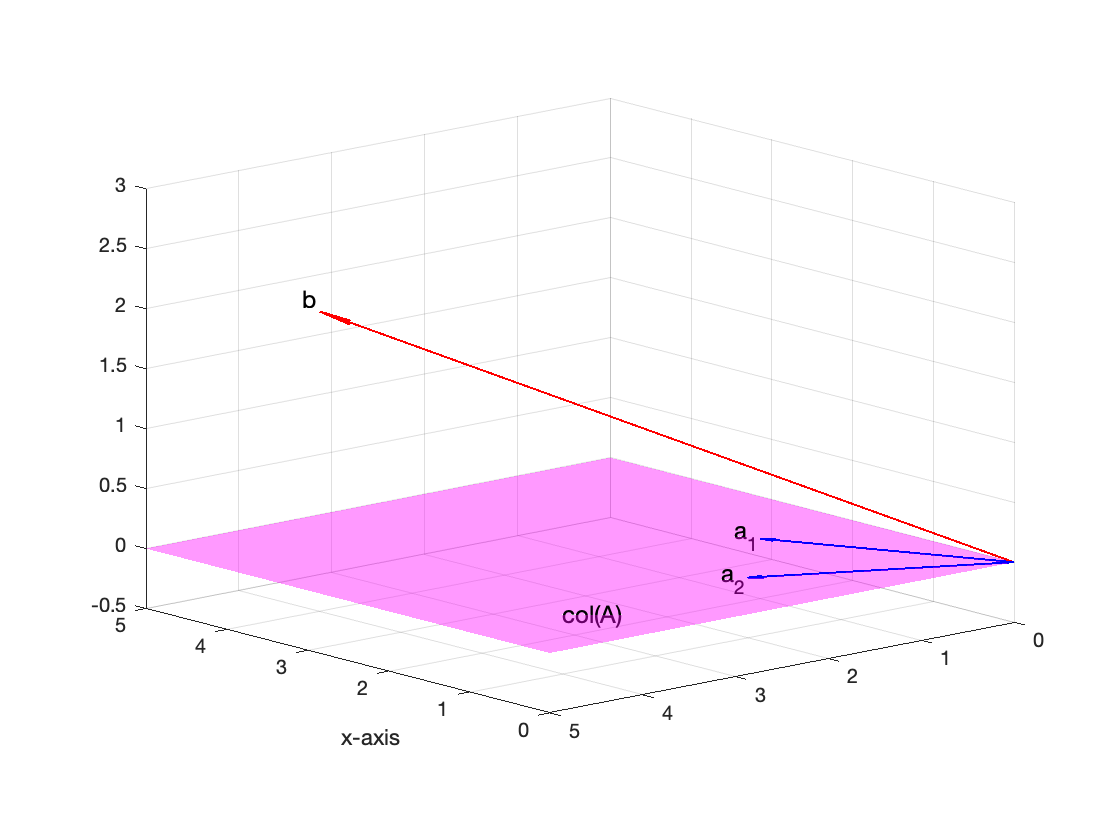

figure
hold on
s=linspace(-5,5,20);
t=linspace(-5,5,20);
[S,T]=meshgrid(s,t);
X=3*S+T;
Y=S+3*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
quiver3(0,0,0,2,1,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,4,4,2,0,'LineWidth',1,'Color','r')
axis equal
axis([0,5,0,5,-0.5,3])
xlabel('x-axis')
grid on
text(2.2,1.1,0,'a_1','FontSize',12)
text(1.1,2.2,0,'a_2','FontSize',12)
text(4.1,4.1,2.1,'b','FontSize',12)
text(1,4,0,'col(A)','FontSize',12)
view(-131,13)
hold off

The system is inconsistent. It doesn't have a solution because $\textbf b\notin \text{col}(A)$, so it cannot be written as a linear combination of the vectors $\textbf a_1$ and $\textbf a_2$, the columns of matrix $A$. Now, what is the linear combination of $\textbf a_1$ and $\textbf a_2$ that lies in the column space of matrix $A$ that is closest to the tip of the vector $\textbf b$? The answer is, the projection of the vector $\textbf  b$ onto the column space of matrix $A$, which we label $\textbf w$ in the following image.

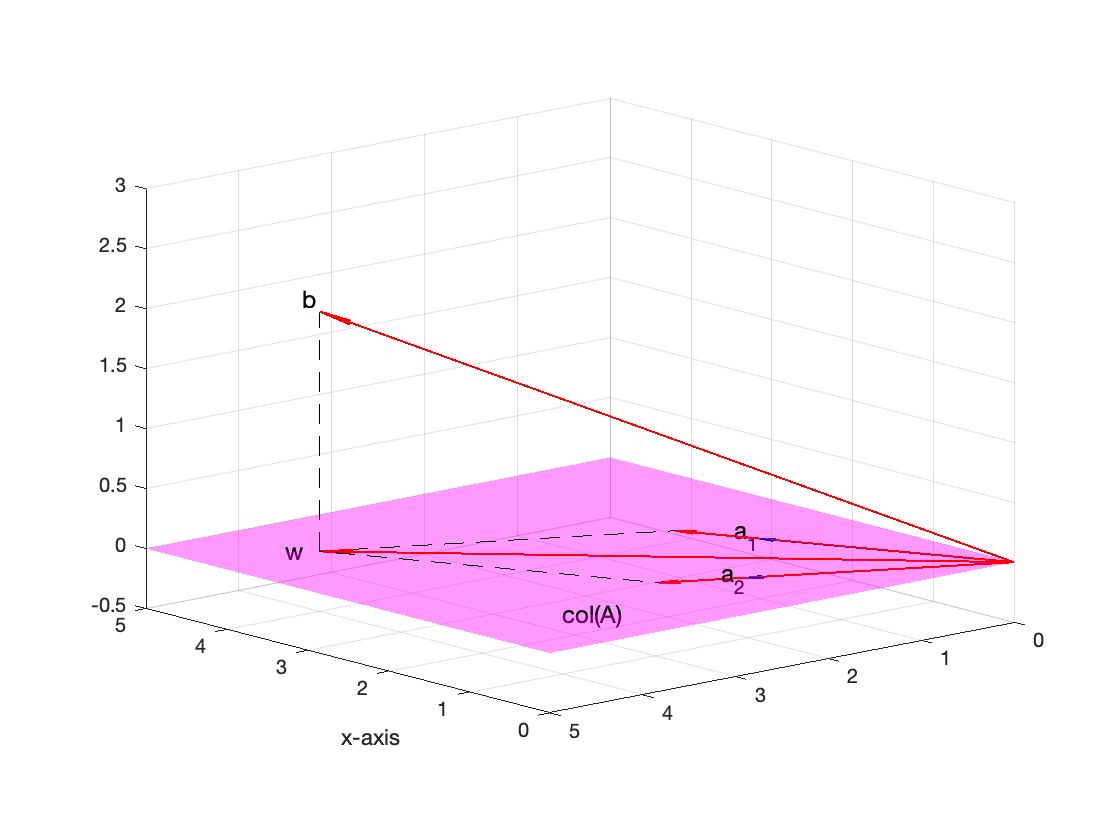

figure
hold on
s=linspace(-5,5,20);
t=linspace(-5,5,20);
[S,T]=meshgrid(s,t);
X=3*S+T;
Y=S+3*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
quiver3(0,0,0,2,1,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,4,4,2,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,2.6666,1.3333,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,1.3333,2.6666,0,0,'LineWidth',1,'Color','r')
line([4,4],[4,4],[0,2],'LineStyle','--','Color','k')
line([1.3333,4,2.6666],[2.6666,4,1.3333],[0,0,0],'LineStyle','--','Color','k')
axis equal
axis([0,5,0,5,-0.5,3])
xlabel('x-axis')
grid on
text(2.2,1.1,0,'a_1','FontSize',12)
text(1.1,2.2,0,'a_2','FontSize',12)
text(4.1,4.1,2.1,'b','FontSize',12)
text(4.2,4.2,0,'w','FontSize',12)
text(1,4,0,'col(A)','FontSize',12)
view(-131,13)
hold off

Note that $\textbf w$, the projection of $\textbf b$ onto the column space of matrix $A$, can be written as a linear combination of $\textbf a_1$ and $\textbf a_2$, the columns of matrix $A$; that is, the system


$$A\hat{\textbf x}=\textbf w$$


has a solution. Note that we've used the variable $\hat{\textbf x}$ due to the fact that we have already used $\textbf x$ in the system $A\textbf x=\textbf b$. Next, let's add the vector $\textbf b-\textbf w$ to our image.

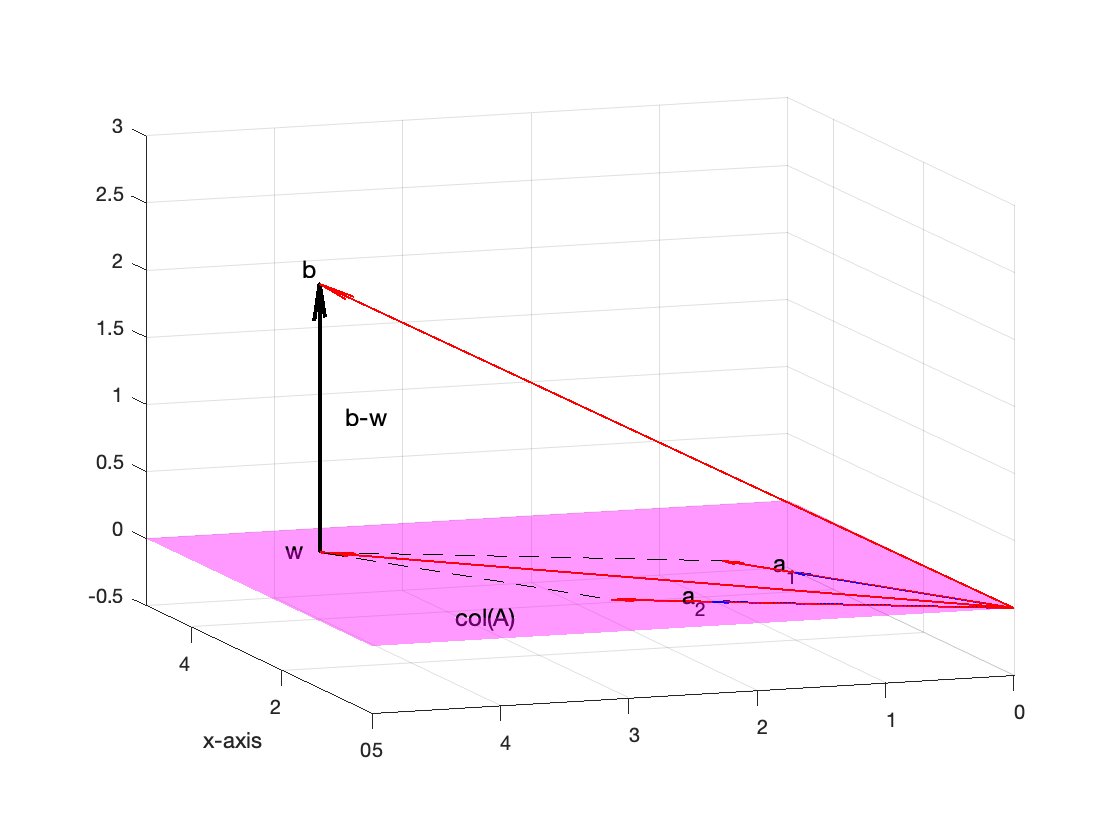

figure
hold on
s=linspace(-5,5,20);
t=linspace(-5,5,20);
[S,T]=meshgrid(s,t);
X=3*S+T;
Y=S+3*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
quiver3(0,0,0,2,1,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,4,4,2,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,8/3,4/3,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,4/3,8/3,0,0,'LineWidth',1,'Color','r')
quiver3(4,4,0,0,0,2,0,'LineWidth',2,'Color','k','MaxHeadSize',0.4)
line([4,4],[4,4],[0,2],'LineStyle','--','Color','k')
line([4/3,4,8/3],[8/3,4,4/3],[0,0,0],'LineStyle','--','Color','k')
axis equal
axis([0,5,0,5,-0.5,3])
xlabel('x-axis')
grid on
text(2.2,1.1,0,'a_1','FontSize',12)
text(1.1,2.2,0,'a_2','FontSize',12)
text(4.1,4.1,2.1,'b','FontSize',12)
text(4.2,4.2,0,'w','FontSize',12)
text(1,4,0,'col(A)','FontSize',12)
text(4,3.8,1,'b-w','FontSize',12)
view([-109.40 9.65])
hold off

Now, because $\textbf b-\textbf w$ is orthogonal to the column space of $A$ (the plane), it lies in $\text{col}(A)^\bot$, which is equal to $N(A^T)$.  Hence,


$$A^T(\textbf b-\textbf w)=\textbf 0$$


Because we said above that $A\hat{\textbf x}=\textbf w$, we can substitute this for $\textbf w$ and do a little manipulation


$$\begin{array}{rcl}
A^T\left(\textbf b-A\hat{\textbf x}\right)&=&\textbf 0\\
A^T\textbf b-A^TA\hat{\textbf x}&=&\textbf 0\\
A^T\textbf b&=&A^TA\hat{\textbf x}
\end{array}$$


or equivalently,


$$A^TA\hat{\textbf x}=A^T\textbf b$$


Now, let's see how this works with our example. 


$$\begin{array}{rcl}
A^TA\hat{\textbf x}&=&A^T\textbf b\\
\pmatrix{2 & 1 & 0\cr 1 & 2 & 0}\pmatrix{2 & 1\cr 1 & 2\cr 0 & 0}\pmatrix{x_1\cr x_2}&=&\pmatrix{2 & 1 & 0\cr 1 & 2 & 0}\pmatrix{4\cr 4\cr 2}\\
\pmatrix{5 & 4\cr 4 & 5}\pmatrix{x_1\cr x_2}&=&\pmatrix{12\cr 12}
\end{array}$$


Now we can multiply both sides by the inverse of the coefficient matrix and continue:


$$\begin{array}{rcl}
\pmatrix{x_1\cr x_2}&=&\pmatrix{5 & 4\cr 4 & 5}^{-1}\pmatrix{12\cr 12}\\
\pmatrix{x_1\cr x_2}&=&\frac{1}{9}\pmatrix{5 & -4\cr -4 & 5}\pmatrix{12\cr 12}\\
\pmatrix{x_1\cr x_2}&=&\frac{1}{9}\pmatrix{12\cr 12}\\
\pmatrix{x_1\cr x_2}&=&\pmatrix{4/3\cr 4/3}

\end{array}$$


This is called the **least squares soluiton**; that is $\hat{\textbf x}=(4/3,4/3)^T$. Now, recall that we said above that $A\hat{\textbf x}=\textbf w$, so we can find our orthogonal projection $\textbf w$ by substituting our least squares soluiton.


$$\begin{array}{rcl}
\textbf w&=&A\hat{\textbf x}\\
\textbf w&=&\pmatrix{2 & 1\cr 1 & 2\cr 0 & 0}\pmatrix{4/3\cr 4/3}\\
\textbf w&=&\pmatrix{4\cr 4\cr 0}
\end{array}$$


Therefore, the orthogonal projection of $\textbf b$  onto the column space of $A$ is $\textbf w=(4,4,0)^T$. Now, if we check our image above, we will see in the code the command quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','r'), which shows our instructor used $\textbf w=(4,4,0)^T$ as the orthogonal projection. Also, note what we get when we multiply 4/3 times the first column of $A$ and $4/3$ times the second column of $A$.


$$\begin{array}{rcl}
\frac43\pmatrix{2\cr 1\cr 0}&=&\pmatrix{8/3\cr 4/3\cr0}\\
\frac43\pmatrix{1\cr 2\cr 0}&=&\pmatrix{4/3\cr8/3\cr 0}
\end{array}$$


If we look at these two commands in our code

quiver3(0,0,0,8/3,4/3,0,0,'LineWidth',1,'Color','r')

quiver3(0,0,0,4/3,8/3,0,0,'LineWidth',1,'Color','r')

we'll see these match our hand-calculated results. 

Now, what about Matlab? Can Matlab find a least square solution? The answer is "Yes." When we use the command A\b, Matlab returns a least squares solution.

A\b

ans =     1.3333
    1.3333


Is that the same as our hand-calculated answer?

[4/3;4/3]

ans =     1.3333
    1.3333


Yes. Now, what about the symbolic toolbox?

sym(A)\b

$$ans = \left(\begin{array}{c} \infty \\ \infty \end{array}\right)$$

See? The symbolic toolbox does not return least squares solutions, but Matlab does.

# Why is it Called a Least Squares Solution?

Our equation $A\textbf x=\textbf b$ did not have a solution, but we found a solution to the equation $A\hat{\textbf x}=\textbf w$, which gave us the following result.

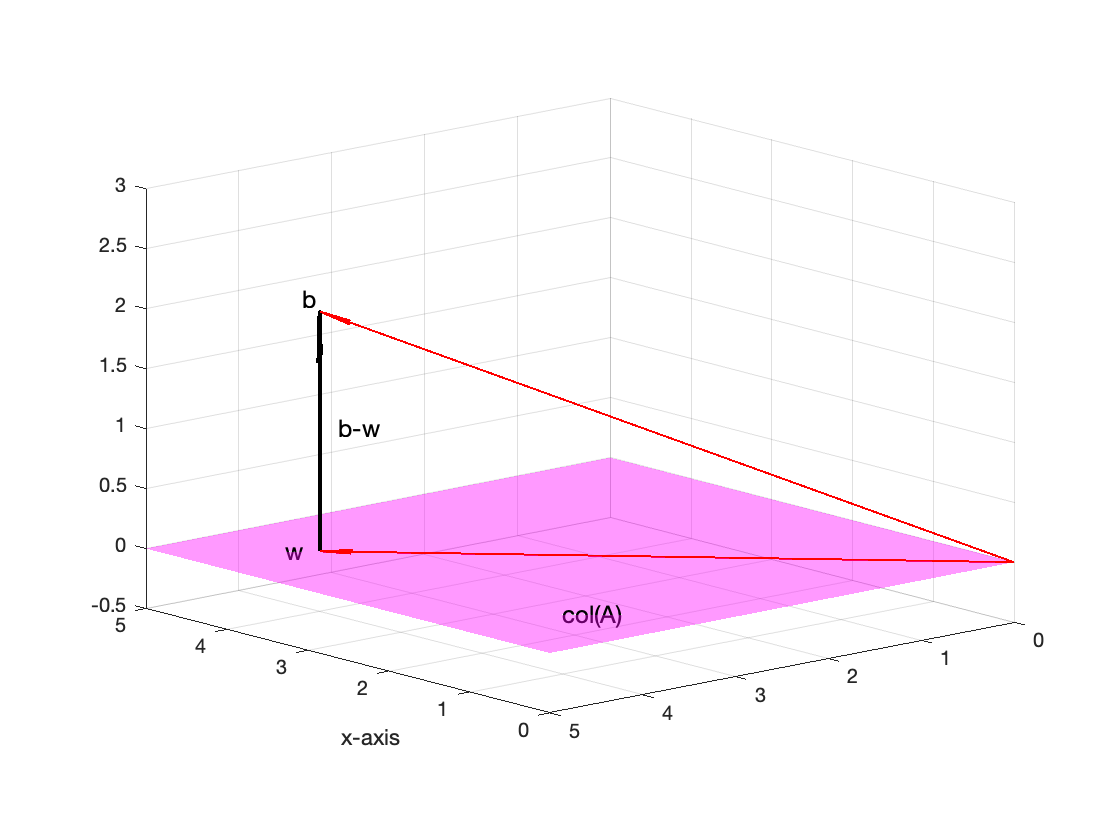

figure
hold on
s=linspace(-5,5,20);
t=linspace(-5,5,20);
[S,T]=meshgrid(s,t);
X=3*S+T;
Y=S+3*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
quiver3(0,0,0,4,4,2,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','r')
quiver3(4,4,0,0,0,2,0,'LineWidth',2,'Color','k','MaxHeadSize',0.6)
axis equal
axis([0,5,0,5,-0.5,3])
xlabel('x-axis')
grid on
text(4.1,4.1,2.1,'b','FontSize',12)
text(4.2,4.2,0,'w','FontSize',12)
text(1,4,0,'col(A)','FontSize',12)
text(4,3.8,1,'b-w','FontSize',12)
view(-131,13)
hold off

We wanted $A\hat{\textbf x}$ to give us the vector $\textbf b$ as an answer, but we got the vector $\textbf w$ instead. Note that the error made is equal to the length of the vector $\textbf b-\textbf w$. Note that we had $\textbf b=(4,2,2)^T$ and $\textbf w=(4,4,0)^T$, so we can calculate the error as follows.


$$\begin{array}{rcl}
||\textbf b-\textbf w||&=&||(4,4,2)-(4,4,0)||\\
||\textbf b-\textbf w||&=&||(0,0,2)||\\
||\textbf b-\textbf w||&=&\sqrt{0^2+0^2+2^2}\\
||\textbf b-\textbf w||&=&\sqrt{4}\\||\textbf b-\textbf w||&=&2
\end{array}$$


And we can check this with Matlab.

b=[4;4;2];w=[4;4;0];
norm(b-w)

ans = 2

Now, let's add another vector $\textbf u=(2,4,0)^T$, a vector in the column space of $A$, to our image.

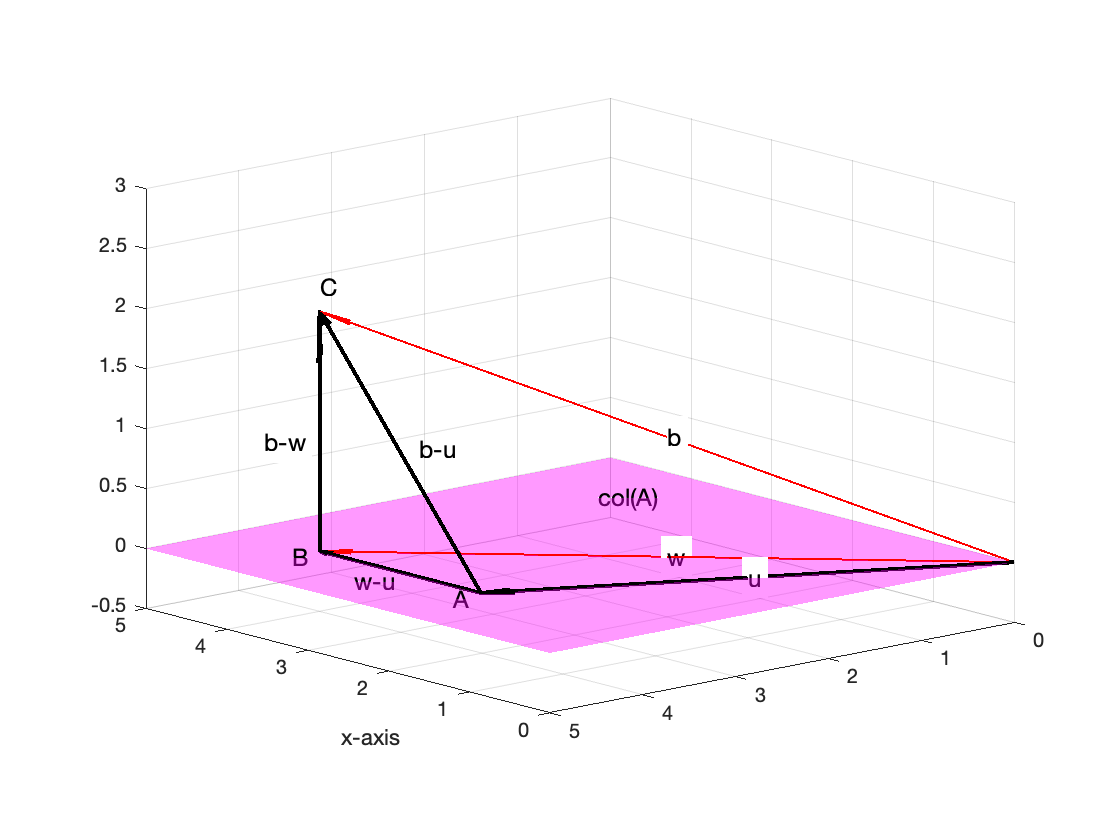

figure
hold on
s=linspace(-5,5,20);
t=linspace(-5,5,20);
[S,T]=meshgrid(s,t);
X=3*S+T;
Y=S+3*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
quiver3(0,0,0,4,4,2,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,4,4,0,0,'LineWidth',1,'Color','r')
quiver3(4,4,0,0,0,2,0,'LineWidth',2,'Color','k','MaxHeadSize',0.6)
quiver3(0,0,0,2,4,0,0,'LineWidth',2,'Color','k','MaxHeadSize',0.2)
quiver3(2,4,0,2,0,0,0,'LineWidth',2,'Color','k','MaxHeadSize',0.2)
quiver3(2,4,0,2,0,2,0,'LineWidth',2,'Color','k','MaxHeadSize',0.2)
axis equal
axis([0,5,0,5,-0.5,3])
xlabel('x-axis')
grid on
text(2,2,1,'b','FontSize',12,'BackgroundColor','w')
text(2,2,0,'w','FontSize',12,'BackgroundColor','w')
text(4,1,0,'col(A)','FontSize',12)
text(4,4.6,1,'b-w','FontSize',12,'BackgroundColor','w')
text(1,2,0,'u','FontSize',12,'BackgroundColor','w')
text(3,4.5,0,'w-u','FontSize',12)
text(3,3.8,1,'b-u','FontSize',12)
text(2,4.3,0,'A','FontSize',12)
text(4,4.3,0,'B','FontSize',12)
text(4,4,2.2,'C','FontSize',12)
view(-131,13)
hold off

Things to note:

- Because $\textbf w, \textbf u\in \text{col}(A)$, $\textbf w-\textbf u\in \text{col}(A)$.

- Because $\textbf b-\textbf w\in\text{col}(A)^\not$, the vector $\textbf b-\textbf w$ is orthogonal to $\textbf w-\textbf u$.

Therefore, triangle $\triangle ABC$ is a right triangle and we can use the Pythagorean Theorem to write:


$$||\textbf b-\textbf u||^2=||\textbf b-\textbf w||^2+||\textbf w-\textbf u||^2$$


But $||\textbf w-\textbf u||^2\ne 0$ because $\textbf w\ne \textbf u$.  Therefore, 


$$||\textbf b-\textbf u||^2=||\textbf b-\textbf w||^2+||\textbf w-\textbf u||^2>||\textbf b-\textbf w||^2$$


which shows that $||\textbf b-\textbf w||^2<||\textbf b-\textbf u||^2$. That is, the tip of the vector $\textbf b$ is further from the tip of the vector $\textbf u$ than it is from the tip of the vector $\textbf w$. That is $||\textbf b-\textbf w||^2$ is the least squares error.

Let's check this with Matlab.

b=[4;4;2];w=[4;4;0];u=[2;4;0];
norm(b-w)

ans = 2

norm(b-u)

ans = 2.8284

This definitely shows that $||\textbf b-\textbf w||<||\textbf b-\textbf u||$.

# Viewing a Lot of Linear Combinations with Matlab

Let's take 10 random linear combinations of the columns of matrix $A$.

A=[2 1;1 2;0 0];
b=[4;4;2];
w=[4;4;0];
V=1-2*rand(2,10);
U=A*V

U =     1.3092    0.1313    1.3123    1.1441   -0.4696   -0.7348   -1.1418    1.1916    0.8279    1.5248
    1.7046    0.7792   -0.1086    0.7448    0.1875   -0.0515   -1.1830    2.0371    0.6410    1.6712
         0         0         0         0         0         0         0         0         0         0


Thus, each column of $U$ is a linear combination of the columns of $A$. Now, if we do b-U, Matlab kindly does b-u for each column u in U.

B=b-U

B =     2.6908    3.8687    2.6877    2.8559    4.4696    4.7348    5.1418    2.8084    3.1721    2.4752
    2.2954    3.2208    4.1086    3.2552    3.8125    4.0515    5.1830    1.9629    3.3590    2.3288
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000


Matlab's **vecnorm** command will return the norm of each column.

vecnorm(B)

ans =     4.0632    5.4166    5.3014    4.7700    6.2059    6.5447    7.5698    3.9674    5.0343    3.9433


Let's check this output by taking the norm of the first column of b-U.

norm(B(:,1))

ans = 4.0632

Same answer. Now, the thing to note is that $||\textbf b-\textbf w||=2$, which is less than all these answers. Some might still doubt this result and ask "How can we select a bunch of vectors that are very near the vector $\textbf w=(4,4,0)^T$?" How about this idea?

X=.1-.2*rand(2,10)

X =    -0.0643   -0.0776   -0.0538   -0.0617    0.0245   -0.0581    0.0345    0.0123   -0.0538   -0.0724
    0.0140    0.0218    0.0206   -0.0510    0.0568   -0.0899   -0.0343   -0.0667    0.0665   -0.0980


Let's add a row of zeros to the matrix X.

X=[X;zeros(1,10)]

X =    -0.0643   -0.0776   -0.0538   -0.0617    0.0245   -0.0581    0.0345    0.0123   -0.0538   -0.0724
    0.0140    0.0218    0.0206   -0.0510    0.0568   -0.0899   -0.0343   -0.0667    0.0665   -0.0980
         0         0         0         0         0         0         0         0         0         0


Now, if we add these to the vector $\textbf w$, we should get a bunch of vectors whose tips are very close to the tip of the vector $\textbf w$.

U=w+X

W =     3.9357    3.9224    3.9462    3.9383    4.0245    3.9419    4.0345    4.0123    3.9462    3.9276
    4.0140    4.0218    4.0206    3.9490    4.0568    3.9101    3.9657    3.9333    4.0665    3.9020
         0         0         0         0         0         0         0         0         0         0


Sure enough, see how they are all close to $\textbf w=(4,4,0)^T$? Now, let's calculuate $||\textbf b-\textbf u||$ for each column of U.

vecnorm(b-U)

ans =     2.0011    2.0016    2.0008    2.0016    2.0010    2.0029    2.0006    2.0011    2.0018    2.0037


The lengths are all larger than $||\textbf b-\textbf w||=2$, so $||\textbf b-\textbf w||$ is a least squares error. 